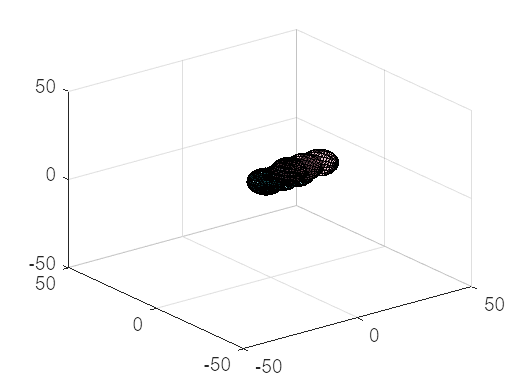

clear all
ax = axes('XLim',[-50 50],'YLim',[-50 50],'ZLim',[-50 50]);
view(3)

R11=6.60;
R31=6.67;

u31=[0.4897;0.8719;0];
u32=[-0.4897;0.8719;0];

[x1,y1,z1] = ellipsoid(3.306,6.650,0,R11,R11,R31,20);
[x2,y2,z2] = ellipsoid(8.454,0,7.345,R11,R11,R31,20);


hold on

h(1)=surf(x1,y1,z1,'FaceColor',[36,133,142]/256, ...
    'FaceAlpha',0.3);

g(1)=surf(x2,y2,z2,'FaceColor',[200,137,153]/256, ...
    'FaceAlpha',0.3);


grid on
hold off

t1 = hgtransform('Parent',ax);
t2 = hgtransform('Parent',ax);
t3 = hgtransform('Parent',ax);
t4 = hgtransform('Parent',ax);
t5 = hgtransform('Parent',ax);
t6 = hgtransform('Parent',ax);

r1 = hgtransform('Parent',ax);
r2 = hgtransform('Parent',ax);
r3 = hgtransform('Parent',ax);
r4 = hgtransform('Parent',ax);
r5 = hgtransform('Parent',ax);
r6 = hgtransform('Parent',ax);


Ry = makehgtform('yrotate',90*pi/180);
Rz1 = makehgtform('zrotate',60.68*pi/180);
Rz2 = makehgtform('zrotate',-60.68*pi/180);

Tr1 = makehgtform('translate',[3.306 6.650 0]);
Tr2 = makehgtform('translate',[8.454 0 7.345]);

Ta = makehgtform('translate',[6.613 0 0]);

set(h,'Parent',t1);
set(g,'Parent',r1);


h2 = copyobj(h,t2);
h3 = copyobj(h,t3);
h4 = copyobj(h,t4);
h5 = copyobj(h,t5);
h6 = copyobj(h,t6);

g2 = copyobj(g,r2);
g3 = copyobj(g,r3);
g4 = copyobj(g,r4);
g5 = copyobj(g,r5);
g6 = copyobj(g,r6);


set(t1,'Matrix',Tr1*Rz1*Ry*Rz1/Tr1)
set(t2,'Matrix',Ta*Tr1*Rz1*Ry*Rz1/Tr1)
set(t3,'Matrix',Ta*Ta*Tr1*Rz1*Ry*Rz1/Tr1)

set(r1,'Matrix',Tr2*Rz2*Ry*Rz2/Tr2)
set(r2,'Matrix',Ta*Tr2*Rz2*Ry*Rz2/Tr2)
set(r3,'Matrix',Ta*Ta*Tr2*Rz2*Ry*Rz2/Tr2)